# Magnetic Levitation Modelling

## Plant modelling

### Magnetostatics

We model the electromagnet as a number of close, stacked rings with an iron core. We assume constant current and use Biot-Savart to find the magnetic field along the axis of a ring:

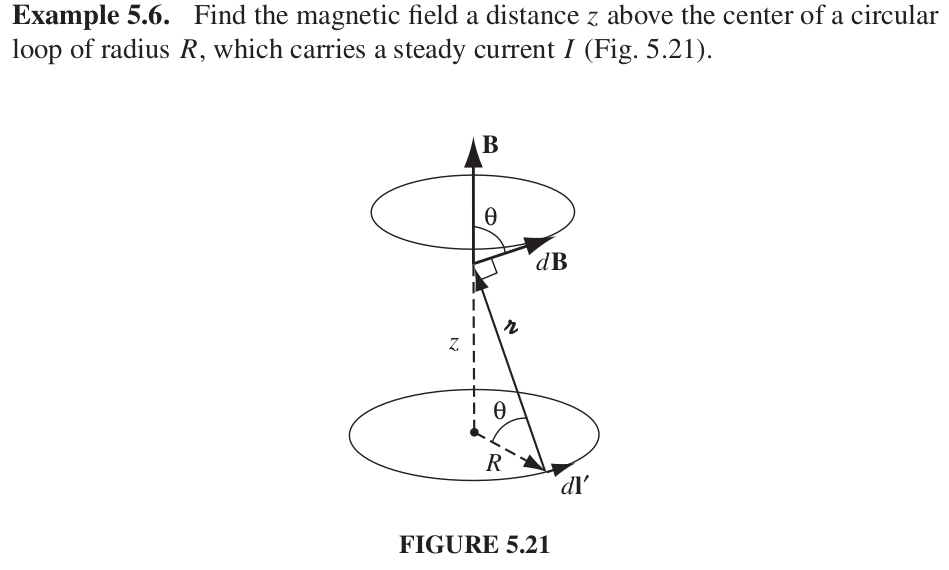

Then, we extend this to multiple close stacked rings that we assume approximate a solenoid:

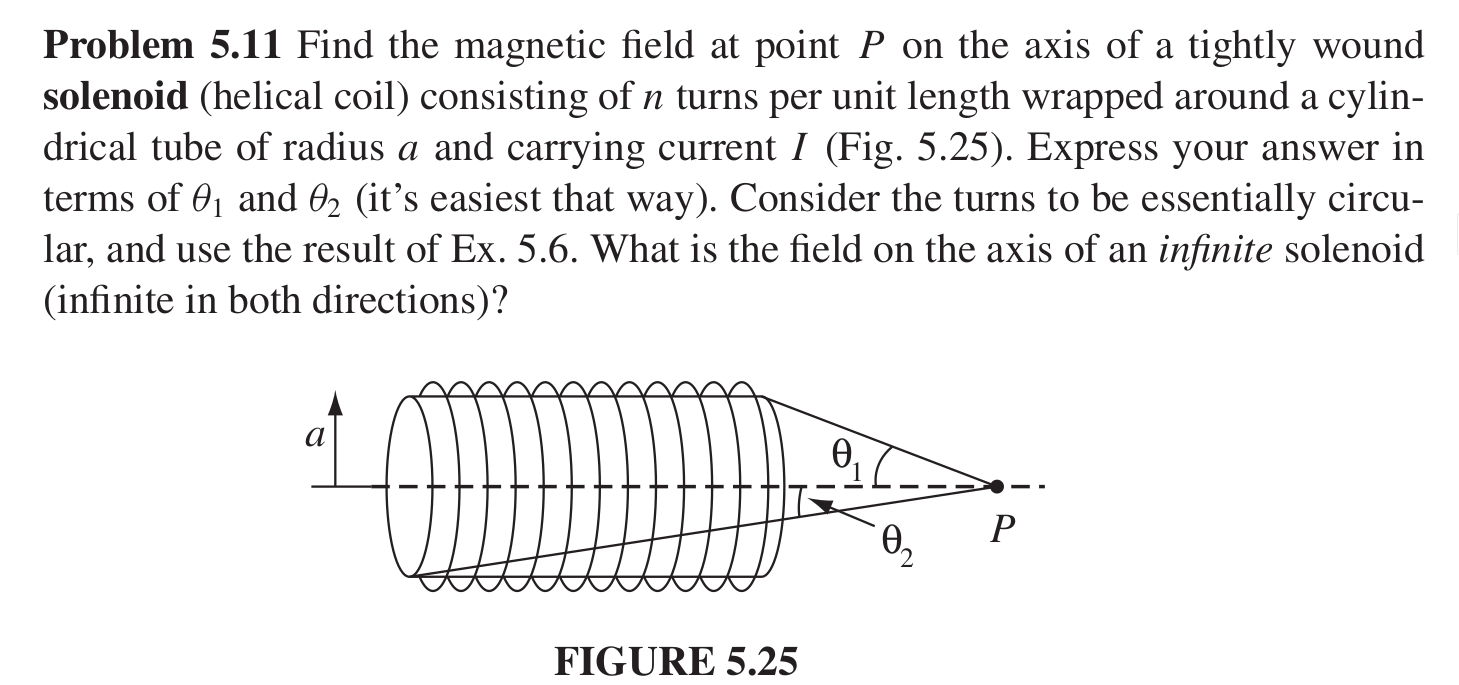

Then we changed the permeability of free space to the permeability of a permanent magnet core material so that our equation for the magnetic field applies for an electromagnet:

$\mu$ is the permeability; $z$ is the distance of  the magnet from the end of the core ($z \hat k$ is $P$ in the above diagram); $r$ is the radius of the solenoid; $l$ is the length of the solenoid; $n$ is  the number of windings; finally, $I$ is the current through the windings.

Finally, we used $F = \nabla(\vec m \cdot \vec B)$ (see Griffiths 4rd ed. page 268; assumes our electromagnet is an infinitely-thin loop) to solve for the force on a magnetic dipole with a magnetic dipole moment $\vec m$ by a magnetic field $\vec B$:

Bill section 2

We currently assume that $\vec m$ (the dipole moment) is parallel with the axis of the solenoid, so there's no torque on the magnet. We could easily extend the above *and* calculate the torque for when the magnet is rotated about its center, but we don't think this is worthwhile because the Hall effect sensor can't differentiate between rotations and translations.

We have force on the permanent magnet by the electromagnet. We add this to the gravitational force on the magnet: $\sum_{ext} = F_{mag}(z(t), i(t)) + mg = m \ddot z(t)$. Our states are therefore $\left[\matrix{\dot z \cr z}\right]$.

### Linearization

Because $F_{mag}(z(t))$ contains another function of $t$, $i(t)$, the current through the electromagnent windings, we need to do a multivariate first-order Taylor series expansion to linearize our equation for the force on the magnet, which is nonlinear. This gives us:


$$F_{mag}(z_{ref}, i_{ref}) \approx F_{mag}(z_{ref}, i_{ref}) + \frac{\partial F_{mag}(z_{ref}, i_{ref})}{\partial z(t)} (z(t) - z_{ref}) + \frac{\partial F_{mag}(z_{ref}, i_{ref})}{\partial i(t)} (i(t) - i_{ref})$$


Bill section 3 (linearization)

### Laplace transform and transfer function

First, we take the Laplace transform of our function

function setup()
    syms mu_iron I n l z r theta_1 theta_2 % Electromagnet parameters
    syms mu_0 p l_mag % Magnet parameters
    
    assume([mu_0 I n l z r p l_mag theta_1 theta_2], 'real')
    assumeAlso([z r], 'positive')
    struct_params = struct();
    struct_params.mu_0 = 1.2e-6; % m kg / (s^2 A^2)
    struct_params.mu_iron = 6.3e-3; % m kg /(s^2 A^2)
    struct_params.n = 50; % # of turns
    struct_params.r = 0.01; % Radius (m)
    struct_params.p = 48; % Pole strength (amp-meters)
    struct_params.l_mag = 0.05; % Length of magnet (m)
    struct_params.l = 0.02; % Length of inductor (m)
    struct_params.z_bar = 0.04;
    struct_params.I_bar = 0.02;
end